warning off
init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git


Adding toolboxes and subfolders to path... 


warning on

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs and (micro)saccade related ERPs.

PROJECTPATH = '/media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/';
EEG = pop_loadset('filename','msaff_15.set','filepath',sprintf('%s/02_sync_data_with_sacc',PROJECTPATH));

pop_loadset(): loading file /media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/02_sync_data_with_sacc/msaff_15.set ...


% there where ~2% saccades with extreme values. We remove it for this demonstration
EEG = eeg_checkset(EEG);
badEv = find([EEG.event.sac_amplitude]>10);
EEG.event(badEv) = [];

% A simple threshold function taken from ERPLAB
% There are dc-offset jumps in the data. This is due to the recording-amplifier
% We remove very noisy data segments (>250mV) from the designmatrix
winrej = dc_continuousArtifactDetect(EEG,'amplitudeThreshold',250);


	So, basicrap.m will be applied over the full range of data.

Please wait. This might take several seconds...

 91 segments were marked.



# Defining the design

cfgDesign = [];
cfgDesign.eventtype = {'saccade'}; % we only model a single event to make the tutorial easier.
% We use intercept-only formulas because we are only interested in the overlap for now
cfgDesign.formula = {'y ~ 1 + spl(sac_amplitude,10)'}; % 10 splines are generated; very high amplitude saccades (>5deg) and small ones (<1deg) show very different behaviour. One needs to be careful to not overfit the data, regularization or cross validation can help here.
EEG = dc_designmat(EEG,cfgDesign);

Modeling event(s) [saccade] using formula: y ~ 1 + spl(sac_amplitude,10) 


We can visualise the set of splines we are using:

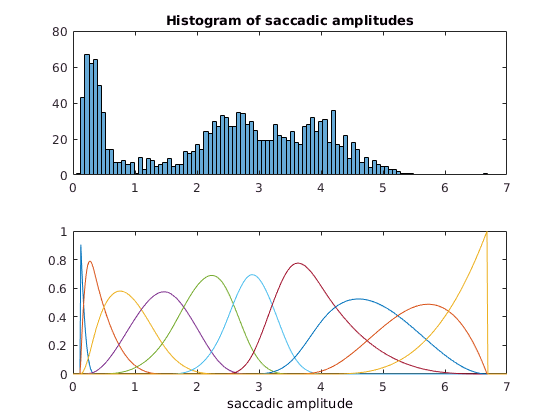

spl = EEG.deconv.predictorSplines{1};

subplot(2,1,1),histogram(spl.paramValues,100),title('Histogram of saccadic amplitudes')
subplot(2,1,2),plot(linspace(0,7,500),Bernstein(linspace(0,7,500),spl.knots,[],4)),xlabel('saccadic amplitude')

The term `spl(sac_amplitude,10)` creates 10 splines over our predictor. The default setting is to put the splines at points of the quantiles of the variable. This ensures that in regions with a lot of data, lots of splines are generated and in regions with sparse data,  broad splines are used. One could also put the splines in a linear or logarithmical way.

The later procedure will fit one beta to each spline (resulting in 9 spline-betas + 1 intercept-beta).

To understand better what basis function do, it might be helpful to have a look at the sorted designmatrix:

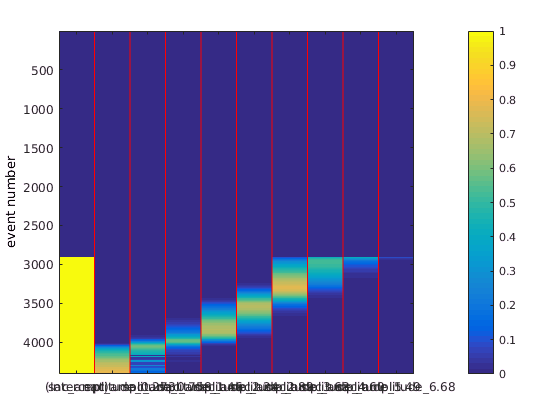

dc_plotDesignmat(EEG,'sort',1)

Not that the empty events  (all blue rows) are events that are not modeled.

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-.3,0.8];

EEG = dc_timeexpandDesignmat(EEG,cfgTimeshift);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


EEG = dc_continuousArtifactExclude(EEG,struct('winrej',winrej));


removing 11.5% from design matrix (fill it with zeros) 


EEG= dc_glmfit(EEG,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 151 iterations, took 30.5s
 LMfit finished 


# Plot the results

Currently the spline-predictor is still separated in intercept + 10 spline-betas. The relationship for e.g. the P100 can be visualized like this:

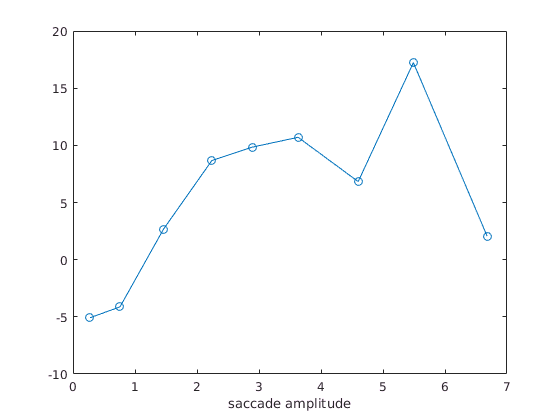

unfold= dc_beta2unfold(EEG);
figure
sac_amp_ix = cellfun(@(x)~isempty(x),(strfind({unfold.param.name},'sac_amplitude'))); % get all betas related to sac_amplitude
timeix = get_min(0.115,unfold.times); % somewhere around the p100

splinevalue = [unfold.param(sac_amp_ix).value];
plot(splinevalue,squeeze(unfold.beta(32,timeix,sac_amp_ix)),'-o'),xlabel('saccade amplitude')

This plot is still lacking the intercept and in generall is somewhat missleading, because the underlying basis functions are overlapping with different overlaps. In order to get a better picture, let's multiply the betas with the basis function to get an estimate in the predictor-value-domain.

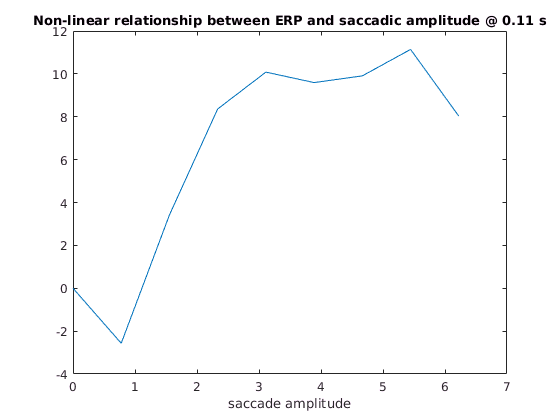


unfold= dc_getParam(unfold,'pred_value',{{'sac_amplitude',linspace(0,7,10)}});
y = unfold.beta(32,timeix,sac_amp_ix); 
% we could add the intercept; it is a constant offset
%y = y + unfold.beta(32,timeix,1);
plot([unfold.param(sac_amp_ix).value],squeeze(y)),xlabel('saccade amplitude'),title(sprintf('Non-linear relationship between ERP and saccadic amplitude @ %.2f s',unfold.times(timeix)))

It is clear from this plot, that there is a strongly non-linear relationship between saccade amplitude and ERP at around 100ms. For high amplitudes, the beta values are smoothed out a lot, because data are sparse and splines were placed at the quantiles.

To really drive home the point we add the weighted splines to the plot:

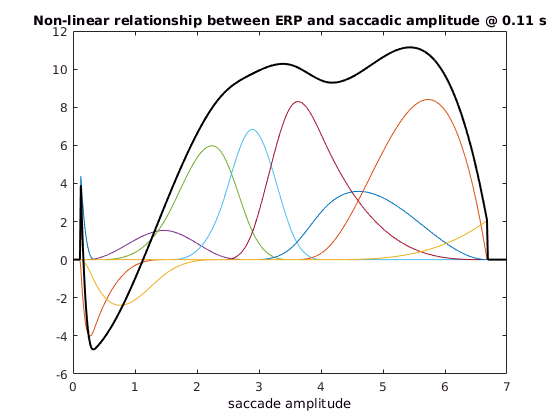

unfold= dc_beta2unfold(EEG);
sacX =linspace(0,7,500); % at which points to evaluate?
splineBasis = Bernstein(sacX,spl.knots,[],4); % get the basis function as above
beta = squeeze(unfold.beta(32,timeix,:));
splineEvaluated = bsxfun(@times,splineBasis,beta'); % weight the basis functions by the betas, but don't add them

plot(sacX,splineEvaluated); hold all;
plot(sacX,sum(splineEvaluated,2),'k','LineWidth',1.5), % add the basis functions at each saccade-amplitude to get the modelfit
xlabel('saccade amplitude'),title(sprintf('Non-linear relationship between ERP and saccadic amplitude @ %.2f s',unfold.times(timeix)))

As one can also see, the modelfit is a bit rough at the edges. this is to be expected because there is not much data for very small and very large splines.

plotting all parameters


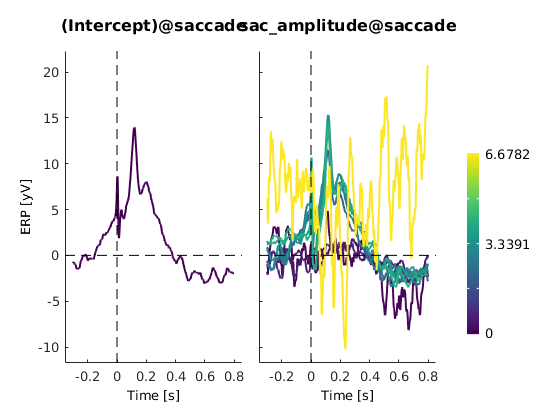

% The default parameters plot the predictor at its quantiles
unfold_to_plot = dc_getParam(unfold); % evaluate the splines at the quantiles
dc_plotParam(unfold_to_plot,'channel',32,'add_average',1);

The upper panel is the response to the average saccade amplitude. The lower one split up by saccade amplitude.

Important notes to this plot:

- The lines represent saccade-amplitudes at the quantiles of the saccade amplitude distribution.

-  There are outliers/bad estimates at the extremes. In the upper example the pink-curve has a very high noise level. This is because the last spline is only informed by a small amount of trials, it is usually highly unstable.

In order to get a more representative picture, we can utilize the `'pred_value' `option in the plot and put a linear spacing excluding the extremata

Evaluating parameters at auto or specified values

plotting all parameters


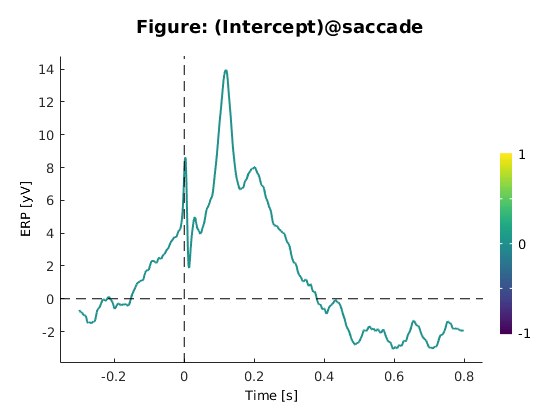

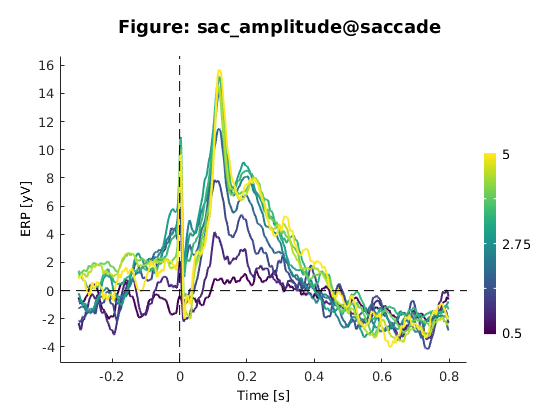

dc_plotParam(unfold,'channel',32,'add_average',1,'pred_value',{{'sac_amplitude',linspace(0.5,5,10)}},'plotSeparate','all');